clear all
clc

iterations = 10^6

iterations = 1000000

Error_counter = 0;

for j = 1:iterations

size = 101;
P = 1;   % assumed 1 since 0db = 1 amplitude

% 1. Generate a sequence of data bits d = {0, 1} with equal probability
d = randi([0 1],1, size);
x = zeros(1, size);
d_hat = zeros(1, size);


% 2. From the data bits generated above, compute the BPSK symbols by encoding 
% bit 0 as -1 and
% bit 1 as +1. That is x = −1 if d = 0 and x = 1 if d = 1

for i = 1:size
    if d(i) == 0
        x(i) = -1;
    else
    x(i) = 1;
    end    
end

% 3. Scale the BPSK symbols by √P so that transmit power is P
x = x.*sqrt(P);

% 4. AWG noise: Generate n ∼ N (0, 1) as Gaussian distributed 
% random numbers with mean 0 and variance σ2 = 1. Use randn() function in Matlab.

n = randn(1,size);

% 5. Compute the received signal as y =√P x + n
y = x + n;   % x already scaled on line 31

% 6. Detector: At the the receiver, the symbols are detected from signal y as

for i = 1:size
    if (real(y(i)) >= 0)
        d_hat(i) = 1;
    else
        d_hat(i) = 0;
    end 
end


% 7. Check if the data bit is received correctly or not. 
% That is no error if d = ˆd and a transmission error if d ̸= ˆd.

d_error = d ~= d_hat;

Error_counter = Error_counter + sum(d_error);
d_error(1:size) = 0;

end

% 8. Repeat the steps 1 to 6 large number of time, 
% around 106 and compute the simulated BER as
tN_bits = size * iterations;
BER_sim = Error_counter / tN_bits

BER_sim = 0.1586

% 9.Vary the transmit power PdB from 0 to 20 dB and compute the BER. 
% Remember that the power is in linear scale, that is P = 0 to 100 
% in linear scale.

clear all
clc

iterations = 10^6

iterations = 1000000

Error_counter = 0;

for j = 1:iterations

size = 101;
P = linspace(0,100,size);

d = randi([0 1],1, size);
x = zeros(1, size);
d_hat = zeros(1, size);


for i = 1:size
    if d(i) == 0
        x(i) = -1;
    else
    x(i) = 1;
    end    
end

x = x.*sqrt(P);

n = randn(1,size);

y = x + n;   % x already scaled

for i = 1:size
    if (real(y(i)) >= 0)
        d_hat(i) = 1;
    else
        d_hat(i) = 0;
    end 
end

d_error = d ~= d_hat;

Error_counter = Error_counter + sum(d_error);
d_error(1:size) = 0;

end

tN_bits = size * iterations;
BER_sim = Error_counter / tN_bits

BER_sim = 0.0082

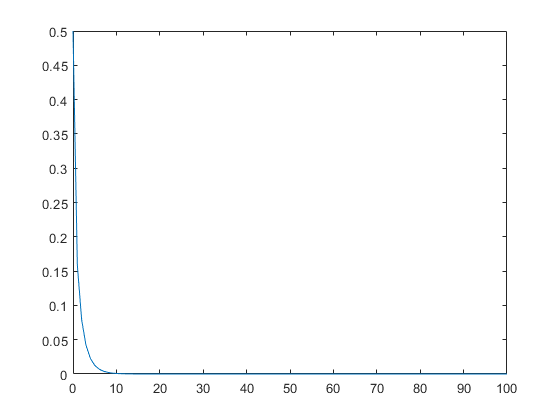

for i = 1:size
P_e(i) = qfunc(sqrt(P(i)));
end

plot(P, P_e)